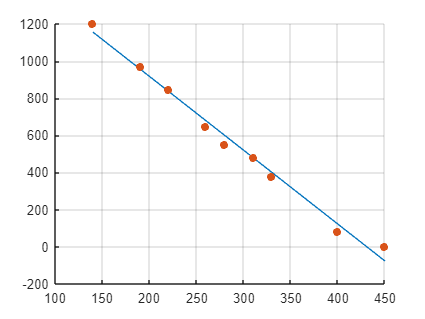

clc
clear
P = [1200 970 845 650 550 480 380 80 0];
Q = [140 190 220 260 280 310 330 400 450];
n = length(P);
syms p(q);
p(q) = curve_fit(Q,P);
p_error = zeros(1,n);
for i = 1 : n
   p_error(i) = abs(P(1,i)-subs(p(q),Q(i)));
end
sum_error = 0;
for i = 1 : n
    sum_error = p_error(i)*p_error(i);
end
hold all
fplot(p(q),[140,450]);
scatter(Q,P,'filled');
grid on

function [output] = curve_fit(x,y)
sum_x = sum(x);
sum_y = sum(y);
N = length(x);
sum_xx = 0;
for i = 1 : N
    sum_xx = sum_xx + x(i)*x(i);
end
sum_xy = 0;
for i = 1 : N
    sum_xy = sum_xy + x(i)*y(i);
end
A = [sum_xx sum_x  ; sum_x N];
d = det(A);
B = [sum_xy ; sum_y];
A_inverse = (1/d)*[N -sum_x ; -sum_x sum_xx];
coeff = A_inverse * B;

syms output(p)
b = vpa(coeff(1));
a = vpa(coeff(2));
output(p) = a + b*p;
end